# Numerieke Lineaire Algebra

## Opgave 2: Iteratieve Methode

clc, clear;

### Bespreek bondig het convergentiegedrag 

A = sprand(1000,1000,0.01);
v = rand(1000,1);

[V, H] = Arnoldi(A,v,100);

V =     0.0444   -0.0140   -0.0224   -0.0011    0.0601   -0.0294   -0.0107   -0.0100   -0.0229    0.0320   -0.0237   -0.0236   -0.0297    0.0170    0.0285    0.0552    0.0209    0.0546    0.0244    0.0302   -0.0290    0.0196   -0.0121    0.0022    0.0185   -0.0548    0.0168   -0.0021    0.0229   -0.0271   -0.0351    0.0053   -0.0031   -0.0000   -0.0072   -0.0092   -0.0181   -0.0182    0.0155   -0.0032   -0.0110    0.0202   -0.0235   -0.0230   -0.0219    0.0171   -0.0350   -0.0357    0.0126    0.0159
    0.0448   -0.0189    0.0687    0.0112    0.0244    0.0572    0.0357    0.0006   -0.0054   -0.0382   -0.0131   -0.0115    0.0181   -0.0320    0.0287   -0.0508   -0.0078    0.0192    0.0088    0.0322   -0.0083    0.0038   -0.0015    0.0302   -0.0078   -0.0777   -0.0159    0.0291    0.0288   -0.0245    0.0617    0.0003    0.0102   -0.0041    0.0618   -0.0390    0.0619   -0.0050   -0.0500   -0.0139   -0.0636   -0.0349   -0.0207   -0.0112    0.0483    0.0644    0.0289    0.0277    0.0307    0

H =     3.7516    1.6047    0.3529    0.0199    0.1253   -0.0153    0.0321    0.0914    0.0830   -0.0437    0.0345   -0.0721    0.0044    0.0759   -0.0336    0.1156    0.0252   -0.0613   -0.0042   -0.0389    0.0915    0.0982   -0.0565   -0.0581    0.0110    0.0122    0.0790    0.0526    0.0585   -0.0344   -0.1329   -0.0516   -0.0022   -0.0400   -0.0761    0.0429    0.1150    0.0040    0.0967   -0.0432    0.0010   -0.0031    0.0180    0.0537    0.0377    0.0184    0.0244    0.0586   -0.1002   -0.0663
    2.8160    0.7072    0.0816    0.1379    0.0115   -0.0895   -0.0407    0.0630   -0.0012    0.0083    0.0398    0.0501    0.0217    0.0514   -0.0492   -0.0026   -0.0065   -0.0801    0.0316   -0.1112    0.0126   -0.0468   -0.0601    0.0074    0.0664    0.0961    0.0264    0.0358   -0.1091   -0.1087   -0.0503    0.0954    0.0274    0.0381   -0.1130   -0.0261    0.0411   -0.0540    0.0243    0.0377    0.1660    0.0540    0.1136   -0.0227   -0.0466   -0.1289    0.0369   -0.0002    0.0544   -0


E = zeros(101,101);
for i = 1:100
    [V, H] = Arnoldi(A,v,i);
    E(1:i+1,i) = eig(V'*A*V);
end

eigA = eigs(A);

eigA =    4.9322 + 0.0000i
   0.4115 + 1.7811i
   0.4115 - 1.7811i
  -1.4753 + 1.0747i
  -1.4753 - 1.0747i
   1.7805 + 0.3835i



best_error = zeros(size(eigA,1), 101);
for i=1:size(eigA,1)
   for k=1:size(E)
        best_error(i,k) = min(abs(E(:,k)-eigA(i)));
   end
end

figure;
title('Opgave 2', 'FontSize', 30);

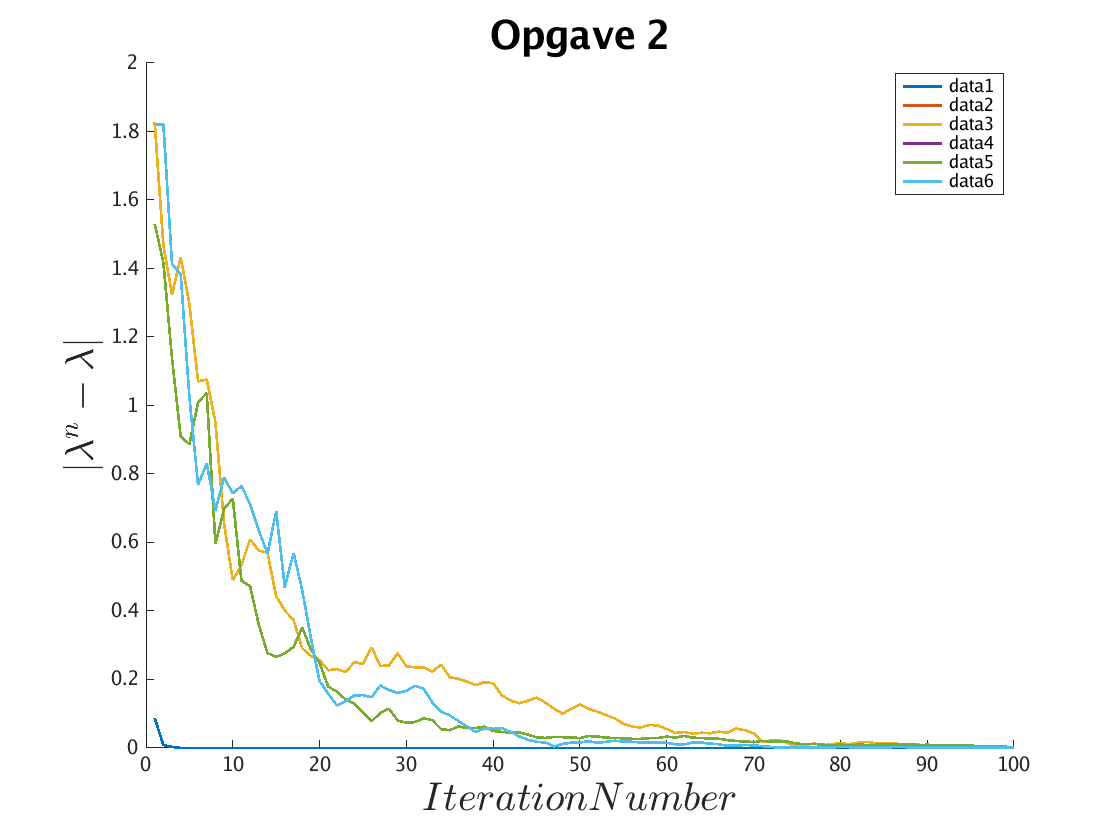

hold on 
plot(best_error(:,1:100)', 'LineWidth', 2)
hold off 
legend('show')
ylabel('$\left| \lambda^{n} -\lambda \right|$','Interpreter','latex', 'FontSize', 30)
xlabel('$Iteration Number$', 'Interpreter','latex', 'FontSize', 30)

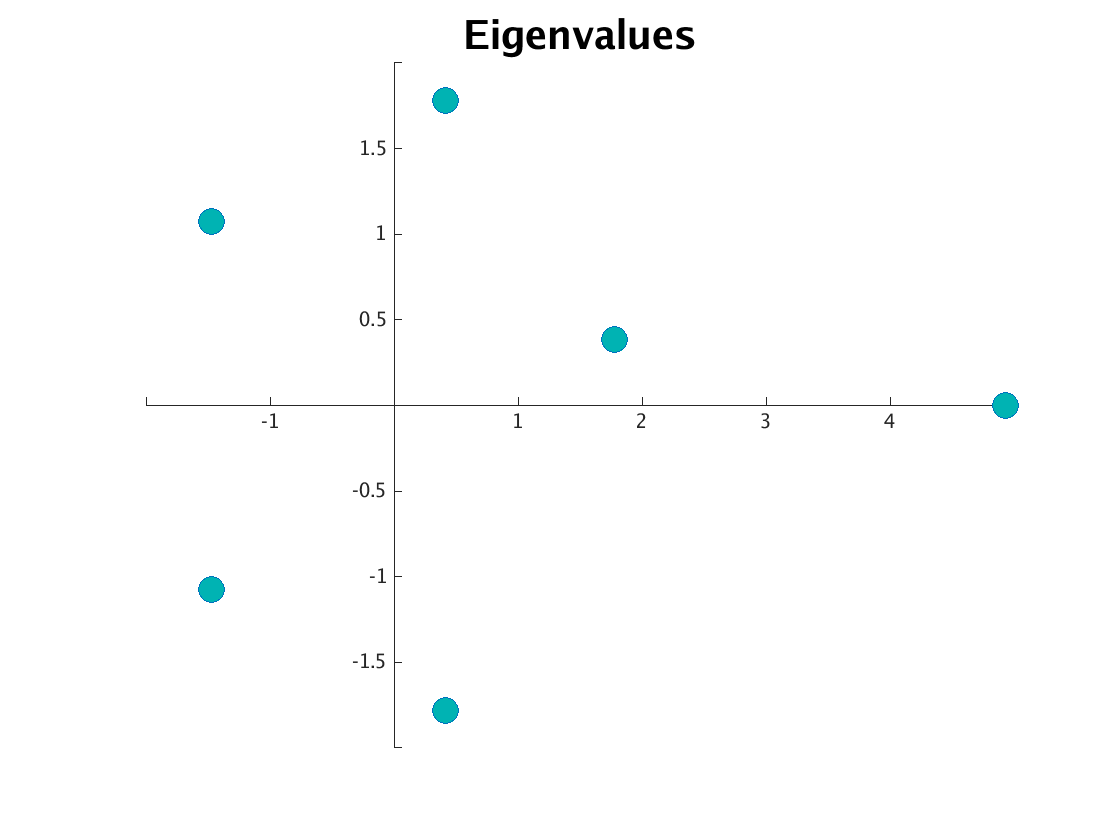

figure;
title('Eigenvalues', 'FontSize', 30);
hold on
plot(eigA,'o','MarkerSize',20,'MarkerFaceColor',[0 0.7 0.7])
hold off
% ylabel('$Imaginary$','Interpreter','latex', 'FontSize', 30)
% xlabel('$Reel$', 'Interpreter','latex', 'FontSize', 30)
ax = gca;                        % gets the current axes
ax.XAxisLocation = 'origin';     % sets them to zero
ax.YAxisLocation = 'origin';     % sets them to zero

ax.Box = 'off';                  % switches off the surrounding box
